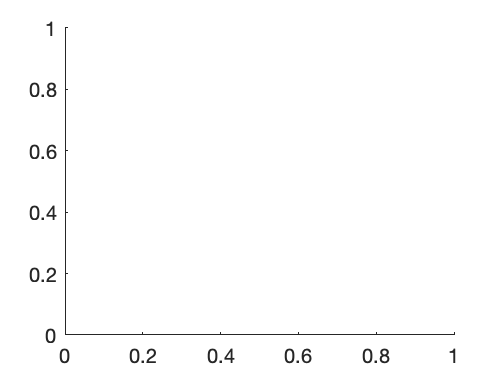

hold off;


%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ";";

% Specify column names and types
opts.VariableNames = ["Workload", "Exit", "Single_record", "Single_replay", "Diff", "Cumulative_record", "Cumulative_replay"];
opts.VariableTypes = ["categorical", "categorical", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Workload", "Exit"], "EmptyFieldRule", "auto");

% Import the data
effectivenessresults = readtable("effectiveness_results.csv", opts);


f = figure;

subplot(3,1,1,'position',[0.1 0.66 0.8 .2]) 

Exit=effectivenessresults.Exit(effectivenessresults.Workload=='OS-BOOT');
Diff=effectivenessresults.Diff(effectivenessresults.Workload=='OS-BOOT');
Workload=effectivenessresults.Workload(effectivenessresults.Workload=='OS-BOOT');
tbl = table(Exit,Diff,Workload);
tbl.Exit(tbl.Exit=='CR_ACCESS')='CR ACCESS';
tbl.Exit(tbl.Exit=='EPT_VIOLATION')='EPT VIOL.';
tbl.Exit(tbl.Exit=='EXTERNAL_INTERRUPT')='EXT. INT.';
tbl.Exit(tbl.Exit=='PENDING_VIRT_INTR')='INT. WI.';
tbl.Exit(tbl.Exit=='IO_INSTRUCTION')='I/O INST.';
tbl.Workload(tbl.Workload=='OS-BOOT')='OS BOOT';

exitOrder = {'I/O INST.','VMCALL','CR ACCESS','CPUID','EPT VIOL.','EXT. INT.','INT. WI.','RDTSC','HLT'};
tbl.Exit = categorical(tbl.Exit,exitOrder);
%workload_oder= {'OS-BOOT', 'IDLE','CPU-bound'};

h(1)=boxchart(tbl.Exit,tbl.Diff,'MarkerStyle', '.','BoxWidth',0.7,'BoxFaceAlpha',1,'LineWidth',1.5,'GroupByColor',tbl.Workload);
meanWeight = groupsummary(tbl.Diff,{tbl.Exit,tbl.Workload},'median');

legend boxoff

hold on
x=[1 3 4 5 6 7 8 ];

h(2)=plot(x,meanWeight,'--*','LineWidth',1)

h =   1×2 graphics array:

    BoxChart    Line    




legend('Orientation','horizontal');
ylim([-15 150])
ax = gca;
ax.XAxis.Visible = 'off';
ax.FontSize = 15;
grid on
ax = gca;
ax.GridColor = [0 0 0];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.3;
ax.Layer = 'top';

legend(h(1));
%set(h(1),'xticklabel',[]);

%ax.FontSize = 20;




hold off;

subplot(3,1,2,'position',[0.1 0.42 0.8 .2]) 


Exit=effectivenessresults.Exit(effectivenessresults.Workload=='CPU-bound');
Diff=effectivenessresults.Diff(effectivenessresults.Workload=='CPU-bound');
Workload=effectivenessresults.Workload(effectivenessresults.Workload=='CPU-bound');
tbl = table(Exit,Diff,Workload);
tbl.Exit(tbl.Exit=='CR_ACCESS')='CR ACCESS';
tbl.Exit(tbl.Exit=='EPT_VIOLATION')='EPT VIOL.';
tbl.Exit(tbl.Exit=='EXTERNAL_INTERRUPT')='EXT. INT.';
tbl.Exit(tbl.Exit=='PENDING_VIRT_INTR')='INT. WI.';
tbl.Exit(tbl.Exit=='IO_INSTRUCTION')='I/O INST.';
tbl.Workload(tbl.Workload=='CPU-bound')='CPU-bound';

exitOrder = {'I/O INST.','VMCALL','CR ACCESS','CPUID','EPT VIOL.','EXT. INT.','INT. WI.','RDTSC','HLT'};
tbl.Exit = categorical(tbl.Exit,exitOrder);
%workload_oder= {'IDLE', 'IDLE','CPU-bound'};

h(1)=boxchart(tbl.Exit,tbl.Diff,'MarkerStyle', '.','BoxWidth',0.7,'BoxFaceAlpha',1,'BoxFaceColor',"r",'MarkerColor','r','LineWidth',1.5,'GroupByColor',tbl.Workload);
meanWeight = groupsummary(tbl.Diff,{tbl.Exit,tbl.Workload},'median');
legend boxoff



hold on
x=[2 3 5 6 7 8 ];

h(2)=plot(x,meanWeight,'--*','LineWidth',1)

h =   1×2 graphics array:

    BoxChart    Line    


ylabel("Code coverage")

legend('Orientation','horizontal');
ylim([-15 150])
ax = gca;
ax.XAxis.Visible = 'off';
ax.FontSize = 15;
grid on
ax = gca;
ax.GridColor = [0 0 0];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.3;
ax.Layer = 'top';
legend(h(1));



hold off;
subplot(3,1,3,'position',[0.1 0.18 0.8 .2]) 


Exit=effectivenessresults.Exit(effectivenessresults.Workload=='IDLE');
Diff=effectivenessresults.Diff(effectivenessresults.Workload=='IDLE');
Workload=effectivenessresults.Workload(effectivenessresults.Workload=='IDLE');
tbl = table(Exit,Diff,Workload);
tbl.Exit(tbl.Exit=='CR_ACCESS')='CR ACCESS';
tbl.Exit(tbl.Exit=='EPT_VIOLATION')='EPT VIOL.';
tbl.Exit(tbl.Exit=='EXTERNAL_INTERRUPT')='EXT. INT.';
tbl.Exit(tbl.Exit=='PENDING_VIRT_INTR')='INT. WI.';
tbl.Exit(tbl.Exit=='IO_INSTRUCTION')='I/O INST.';
tbl.Workload(tbl.Workload=='IDLE')='IDLE';

exitOrder = {'I/O INST.','VMCALL','CR ACCESS','CPUID','EPT VIOL.','EXT. INT.','INT. WI.','RDTSC','HLT'};
tbl.Exit = categorical(tbl.Exit,exitOrder);
%workload_oder= {'CPU-bound', 'CPU-bound','CPU-bound'};

h(1)=boxchart(tbl.Exit,tbl.Diff,'MarkerStyle', '.','BoxWidth',0.7,'BoxFaceAlpha',1,'BoxFaceColor',"#EDB120", 'MarkerColor',"#EDB120",'LineWidth',1.5,'GroupByColor',tbl.Workload);
meanWeight = groupsummary(tbl.Diff,{tbl.Exit,tbl.Workload},'median');
legend boxoff

hold on
x=[2 3 5 6 7 8 9];

h(2) = plot(x,meanWeight,'--*','LineWidth',1)

h =   1×2 graphics array:

    BoxChart    Line    


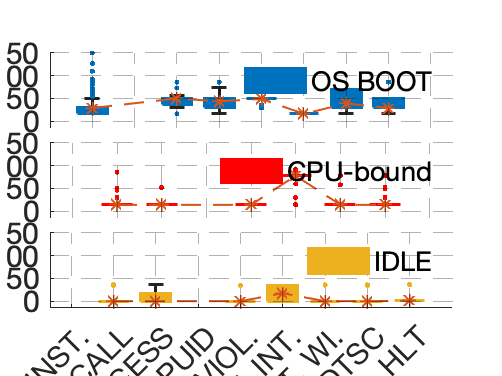



legend('Orientation','horizontal');
ylim([-15 150])
ax = gca;
ax.XAxis.Visible = 'on';
ax.FontSize = 15;
grid on
ax = gca;
ax.GridColor = [0 0 0];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.3;
ax.Layer = 'top';
legend(h(1));

exportgraphics(f, strcat(fileparts(pwd),'/figures/coverage_diffs.pdf'),'BackgroundColor','none')


%print(a2, strcat(fileparts(pwd),'/figures/diff.pdf'),'-dpdf','-r0');



